# main.mlx

clc, clear, close all
datetime("now")

ans = datetime
   11-Nov-2023 23:45:43


## Константы

hbar = 1.054e-34;
e = 1.602e-19;
m0 = 9.109e-31;
n = input("Введите количество решений: ");   % количество запрошенных решений
dz = 0.5e-10;                                % разрешение сетки [м]
F0 = input("Введите величину поля, В/м: ");  % электрическое поле [Вольт/метр]
T = input("Введите температуру, К: ");       % Температура [Кельвины] 


str = sprintf("1 - GaAs/InGaAs20/GaAs\n" + ...
    "2 - AlGaAs40/GaAs/AlGaAs40\n" + ...
    "3 - AlInAs/InGaAs/AlInAs\n" + ...
    "4 - AlInAs/InGaAs/AlInAs/InGaAs/AlInAs\n" + ...
    "5 - AlInAs/InGaAs/AlInAs/InGaAs/AlInAs/InGaAs/AlInAs\n" + ...
    "6 - GaAsSb/InGaAs/GaAsSb\n" + ...
    "Введите номер материала: ");

num_of_mat = input(str);

library;                                     % загрузка базы данных параметров материалов
extract_parameters;                          % извлекаем параметры из библиотеки
ternary_alloy;                               % вычисляем тройной сплав

M = input_file(num_of_mat);                  % выбор материала

## Получение параметров

zt  = M(:, end) * 1e-9;                      % перевод длины из Ангстрема в метр

% Расчёт запрещённой зоны
%Eg = Eg0 - (a*T.^2)./(T + b);
Egt = M(:, idx_Eg6c) - (M(:, idx_alphaG) * T ^ 2) ./ (T + M(:, idx_betaG));
VBOt = M(:, idx_VBO);                        % Смещение валентной зоны

Egt = Egt + VBOt;
% Эффективная масса
met = M(:, idx_me);

## Дискретизация

% вектор координат
z(1) = 0;
% вектор для потенциального профиля
V0(1) = Egt(1);
% вектор эффективных масс
me(1) = met(1);

for i = 1 : length(zt)
    z_tmp = (z(end) + dz) : dz : (z(end) + zt(i));
    z = [z  z_tmp];
    V0 = [V0  ones(size(z_tmp)) * Egt(i)];
    me = [me  ones(size(z_tmp)) * met(i)];
end

V0 = V0 - min(V0);
% добавление электрического поля к потенциалу
V0 = (F0 * z) + V0;

% Нахождение энергии и волновой функции
[E{1}, psi{1}] = FDT_ef_mass(z, V0, me, n);

## Нормализация волновой функции

for k = 1 : length(E)
  for i = 1 : length(E{k})
      PSI{k}(:, i) = abs(psi{k}(:, i)) .^ 2 / max(abs(psi{k}(:, i)) .^ 2) * 0.1 + E{k}(i);
  end
end

## Построение графика

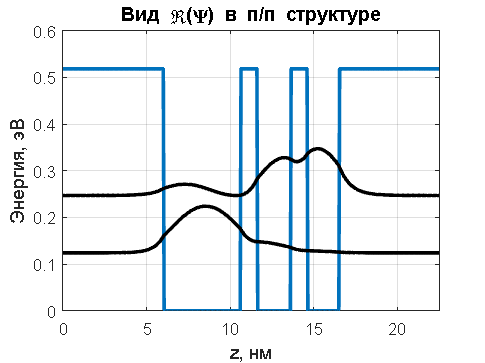

plot(z * 1e9, V0, 'Linewidth', 2);
hold on;
grid on;

for j = 1 : length(E)
  for i = 1 : length(E{j})
      plot(z * 1e9, PSI{j}(:, i), 'color' , 'k', 'Linewidth', 2);
  end
end

xlabel('z, нм');
ylabel('Энергия, эВ');

xlim([0 z(end) * 1e9]);

title("Вид \Re(\Psi) в п/п структуре");